# Basic Rock

This notebook covers the basic functionalities of specifying rock properties of reservoirs. In the .mlx file, there are controls that allow the modification of these properties.

clear;

## Example Grid Definition

Base grid properties:

num_cell_x = 40;
num_cell_y = 40;
num_cell_z = 40;
len_x = 50;
len_y = 50;
len_z = 50;
topside_dist = 30;

G = cartGrid([num_cell_x, num_cell_y, num_cell_z], [len_x, len_y, len_z]);
G = computeGeometry(G);

Remove cells according to function desired:

c = G.cells.centroids;
criteria = c(:,3) - ((4*len_z/(len_x^2))*((c(:,1) - len_x/2).^2)+(4*len_z/(len_y^2))*((c(:,2) - len_y/2).^2));
G = removeCells(G, criteria<0);
c = G.cells.centroids;
criteria = c(:,3) - ((4*len_z/(len_x^2))*((c(:,1) - len_x/2).^2)+(4*len_z/(len_y^2))*((c(:,2) - len_y/2).^2));
G = removeCells(G, criteria>topside_dist);
G = computeGeometry(G);

Plot grid:

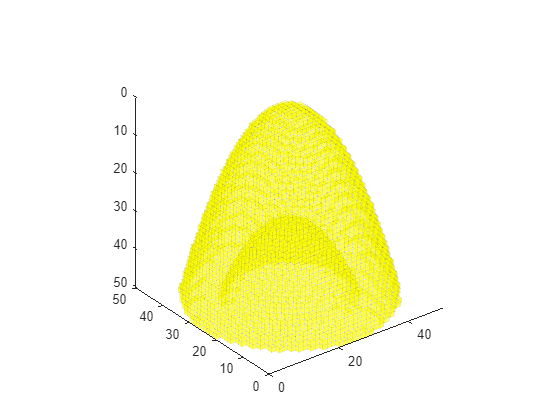

clf;
plotGrid(G,'EdgeAlpha', 0.05, 'FaceAlpha', 0.5)
view(3)
axis equal

## Uniform Rock

The first example is of a uniform rock, where both the permeability and porosity are defined by scalars "perm" and "poro", which compose the "rock" struct:

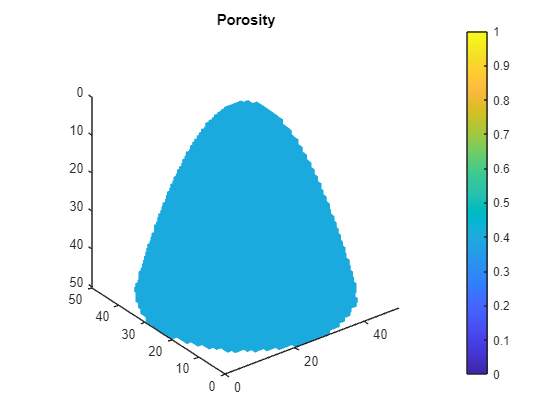

perm = 100;
poro = 0.4;
rock = makeRock(G, perm*milli*darcy, poro);

clf;
plotCellData(G,rock.poro,'EdgeColor','none');view(3),title('Porosity')
view(3), colorbar, axis equal, clim([0 1])

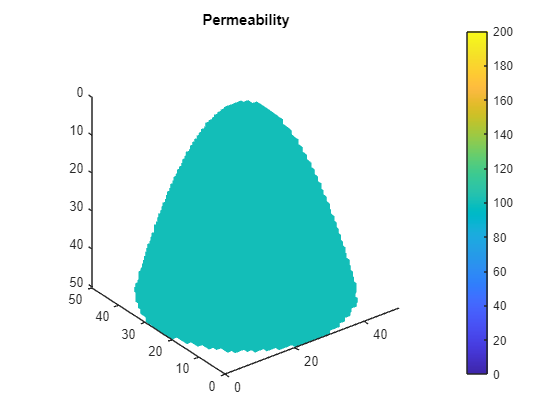


clf;
plotCellData(G,rock.perm/(milli*darcy),'EdgeColor','none');view(3),title('Permeability')
view(3), colorbar, axis equal, clim([0 200])

Alternatively, the permeability can be described as a three index vector:

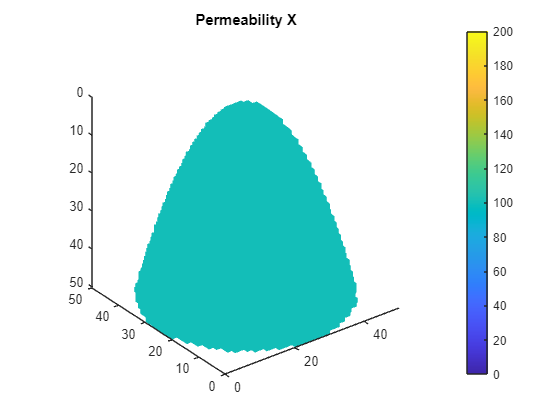

perm(1) = 100;
perm(2) = 100;
perm(3) = 20;
poro = 0.4;
rock = makeRock(G, perm*milli*darcy, poro);

clf;
plotCellData(G,rock.perm(:,1)/(milli*darcy),'EdgeColor','none');view(3),title('Permeability X')
view(3), colorbar, axis equal, clim([0 200])

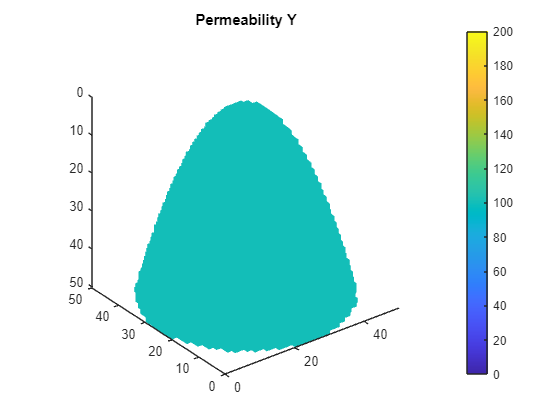

clf;
plotCellData(G,rock.perm(:,2)/(milli*darcy),'EdgeColor','none');view(3),title('Permeability Y')
view(3), colorbar, axis equal, clim([0 200])

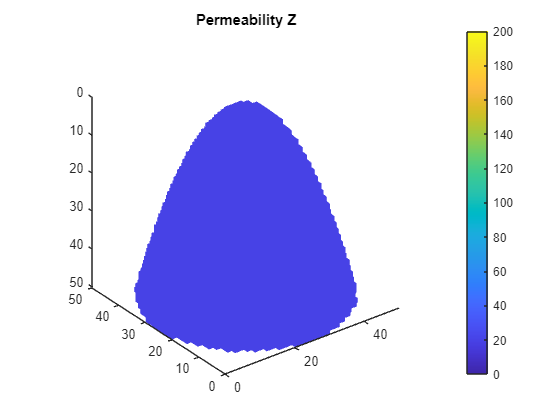

clf;
plotCellData(G,rock.perm(:,3)/(milli*darcy),'EdgeColor','none');view(3),title('Permeability Z')
view(3), colorbar, axis equal, clim([0 200])

## Random Rock

A more complex model can be made using geostatiscal models, correlating permeability and porosity. First, we can generate the porosity as a gaussian field. To do so, we must set a lower and upper bound to the porosity value:

**Important**

**Another reservoir was set up as it was not possible to use this technique with reservoirs with cells removed.**

G_alt = cartGrid([num_cell_x, num_cell_y, num_cell_z], [len_x, len_y, len_z]);
G_alt = computeGeometry(G_alt);

lower_poro = 0.2;
upper_poro = 0.4;

Other parameters are needed to convolute the field and set a standard deviation:

sze(1) = 7;
sze(2) = 7;
sze(3) = 5;

std_dev = 1.3;

Define the porosity:

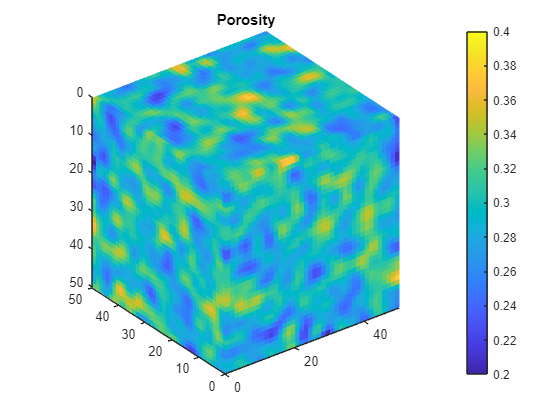

p = gaussianField(G_alt.cartDims, [lower_poro upper_poro], sze, std_dev);
K = p.^3.*(1e-5)^2./(0.81*72*(1-p).^2);
rock = makeRock(G_alt, K(:), p(:));

clf;
plotCellData(G_alt,rock.poro,'EdgeColor','none');view(3),title('Porosity')
view(3), colorbar, axis equal, 
clim([lower_poro, upper_poro])

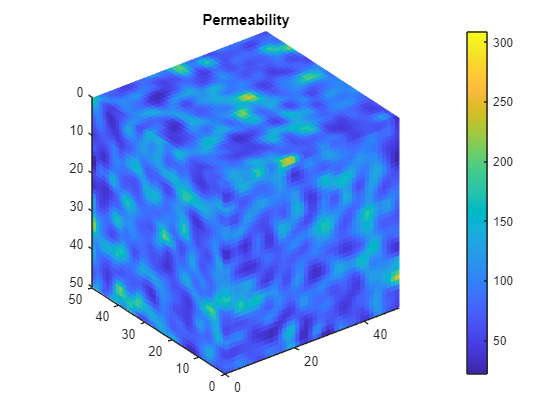

clf;
plotCellData(G_alt,rock.perm/(milli*darcy),'EdgeColor','none');view(3),title('Permeability')
view(3), colorbar, axis equal, 

## Lognormal Layers

Finally, we can use lognormal layers to mimic the effect of geological layers being stacked on one another, leading to layers with distinctive average permeabilities. Consider 4 layers for this example, let's set their permeabilities:

perm_1 =400;
perm_2 =50;
perm_3 =150;
perm_4 =500;

max_n = floor(num_cell_z/3);

n_1 = 11;
n_2 = 9;
n_3 = 10;
n_4 = num_cell_z - n_1 - n_2 - n_3

n_4 = 10

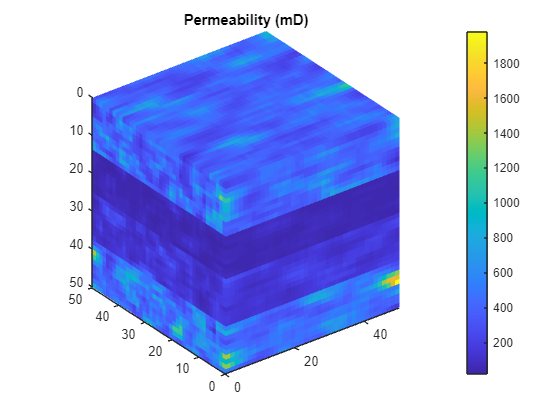


limit_index = num_cell_z + 1;

perm_sigma = 2;
perm_a = 0.9;
perm_b = 2;
perm_sz(1) = 9;perm_sz(2) = 3;
perm_sz(3) = 3;
perm_std = 4.5;

K = logNormLayers(G_alt.cartDims, [perm_1 perm_2 perm_3 perm_4], ...
    'indices', [1 (1 + n_1) (1 + n_1 + n_2) (1 + n_1 + n_2 + n_3) (num_cell_z+1)], ...
    'sigma', perm_sigma, ...
    'a', perm_a, ...
    'b', perm_b, ...
    'sz', perm_sz, ...
    'std', perm_std);

clf;
plotCellData(G_alt,K,'EdgeColor','none');view(3),title('Permeability (mD)')
view(3), colorbar, axis equal, 